clc, clear, close all
format short g

%carga 

r = 220; %[ohms]

%fuente trifasica

mVf = 120; %[V] rms magnitud de la fuente trifasica
f = 60;
w = 2*pi*f;

aVAN = 0; % angulos de cada tension
aVBN = -120;
aVCN = 120;

VAN = mVf*(cosd(aVAN)+j*sind(aVAN))

VAN =    120


VBN = mVf*(cosd(aVBN)+j*sind(aVBN))

VBN =           -60 -     103.92i


VCN = mVf*(cosd(aVCN)+j*sind(aVCN))

VCN =           -60 +     103.92i


calculamos la capacitancia necesaria para tener un angulo de impedancia de -70°

syms angulo f C R

ec1 = solve(tan(angulo)==(1/(2*pi*f*C))/R,C)

$$ec1 = \frac{1}{2\,R\,f\,\pi \,\tan\left(\mathrm{angulo}\right)}$$

r = 220; %[ohms]
f = 60;
c = 1/(2*r*f*pi*tand(-70))

c =   -4.3885e-06


sabiendo la capacitancia, calculamos la reactancia y la impedancia:

xc = 1/(2*pi*f*c)*j

xc =             0 -     604.45i


z1 = r + xc; %impedancia con angulo requerido de -70°
z1_polar = [abs(z1) angle(z1)*180/pi] 

z1_polar =        643.24          -70


z2 = r

z2 =    220


z3 = r

z3 =    220


teniendo las impedancias, calculamos las corrientes de linea

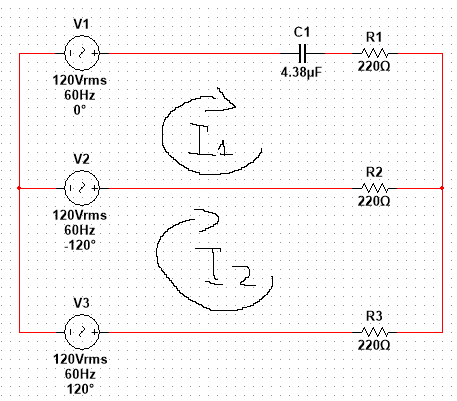

realizamos un analisis de mallas

%tensiones de linea
VAB = VAN-VBN;
VAB_fasor = [abs(VAB) angle(VAB)*180/pi]

VAB_fasor =        207.85           30


VBC = VBN-VCN;
VBC_fasor = [abs(VBC) angle(VBC)*180/pi]

VBC_fasor =        207.85          -90


VAC = VAN-VCN;
VAC_fasor = [abs(VAC) angle(VAC)*180/pi]

VAC_fasor =        207.85          -30


%analisis de malla para i1 e i2

syms i1 i2 r1 r2 r3 v1 v2 v3

ec1 = simplify(v2*(i1-i2) - v1*i1 + r1*i1 + r2*(i1-i2) == 0)

$$ec1 = i_{1}\,\left(r_{1}+r_{2}+v_{2}\right)=i_{2}\,r_{2}+i_{1}\,v_{1}+i_{2}\,v_{2}$$

ec2 = simplify(v3*i2 - v2*(i2-i1) + r2*(i2-i1) + r3*i2 == 0)

$$ec2 = i_{2}\,r_{3}+i_{2}\,v_{3}+v_{2}\,\left(i_{1}-i_{2}\right)=r_{2}\,\left(i_{1}-i_{2}\right)$$

m = [(z1+z2) -(z2); -(z2) (z3+z2)];
n = [VAB;VBC];
h = m\n;

i1 = h(1);
i1_fasor = [abs(i1) angle(i1)*180/pi]

i1_fasor =       0.26138       61.367


i2 = h(2);
i2_fasor = [abs(i2) angle(i2)*180/pi]

i2_fasor =       0.36311      -80.069


Sabemos que

IAa = i1;
IBb = i2-i1;
ICc = -i2;

IAa_fasor = [abs(IAa) angle(IAa)*180/pi]

IAa_fasor =       0.26138       61.367


IBb_fasor = [abs(IBb) angle(IBb)*180/pi]

IBb_fasor =       0.59041      -96.089


ICc_fasor = [abs(ICc) angle(ICc)*180/pi]

ICc_fasor =       0.36311       99.931


Lo verificamos en el simulador:

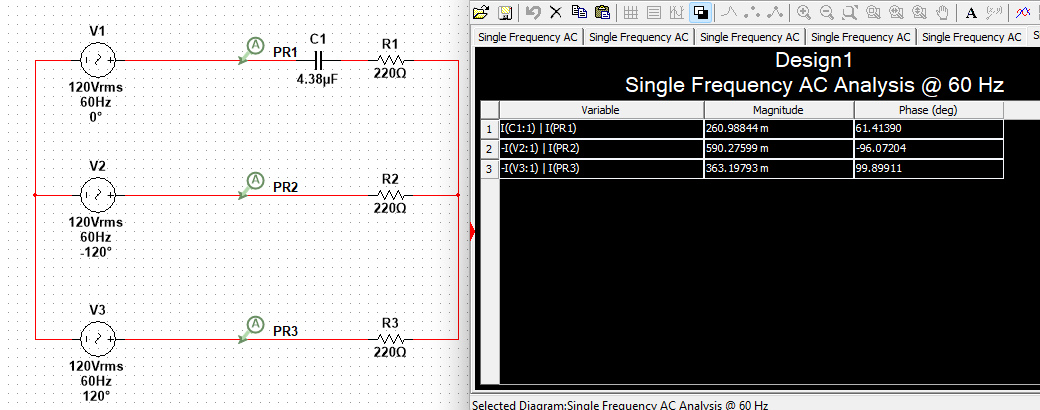

Ahora que tenemos las corrientes podemos calcular la potencia compleja

S_r1 = (IAa*z1)*conj(IAa) 

S_r1 =         15.03 -     41.294i


S_r2 = (IBb*z2)*conj(IBb) 

S_r2 =         76.69


S_r3 = (ICc*z3)*conj(ICc) 

S_r3 =        29.007


S_trifasica = S_r1 + S_r2 + S_r3

S_trifasica =        120.73 -     41.294i


S_trifasica_polar = [abs(S_trifasica) angle(S_trifasica)*180/pi]

S_trifasica_polar =        127.59      -18.883


comparamos con el metodo de los dos vatimetros

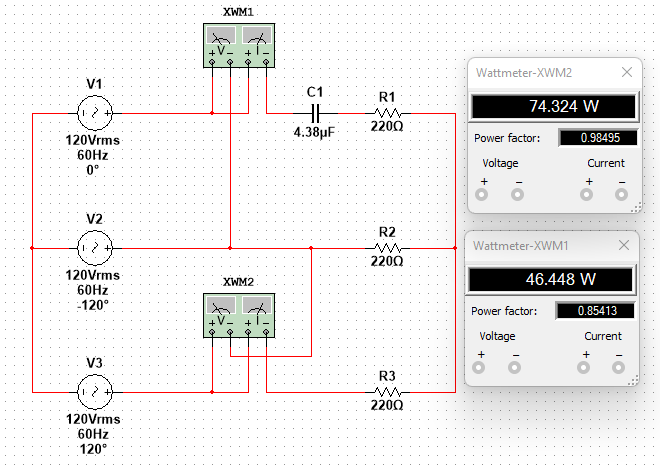

vemos que la suma de las dos lecturas de los vatimetros nos da igual al valor calculado de parte activa de la potencia compleja calculada anteriormente